# DSZOB, cvičenie 3.

## **Zadanie:**

## **Úloha 1 **

Vygenerujte si nasledujúce signály podľa predchádzajúcich cvičení:

- jednoduchý signál

- zložený signál (z troch jednoduchých signálov)

- jednoduchý signál so zníženou vzorkovacou frekvenciou s porušením Nyquistovho teorému

Pre vytvorené signály:

- Z daných signálov vyberte vhodnú vzorku 512 hodnôt, vypočítajte a vizualizujte Diskrétnu Fourierovu transformáciu podľa definície.

- Následne vypočítajte a vizualizujte príslušnú inverznú Fourierovu transformáciu. Aký je výstup? 

- Výpočet DFT a IDFT implementujte ako samostatné funkcie. 

- Výstup DFT vizualizujte, pričom spektrálne indexy prevediete na Hz. (fftshift a druhá polovica výstupu; prepočet od 0 do Fs/2 Hz, index-1)

- K signálom pripočítajte konštantnú hodnotu  (DC komponentu). Vypočítajte DFT a vizualizujte (originál výstup a aj pomocou fftshift) . Kde je možné vo vypočítanej DFT DC komponentu identifikovať?

## Pomôcka (definícia):

- počet prvkov vo vektore

- index spektrálnych koeficientov

- index vzorku vo vstupnom vektore (číslicový signál o dĺžke N)

## Pomôcka:

- pozor na názov funkcií

- fftshift()

- stem()

- abs()

- j

**Postup vhodne dokumentuje (Code/Text bloky)!**

**Pri vizualizácií zamedzte zobrazovaniu upozornení.**

## **Riešenie:**

## **Simple signals**

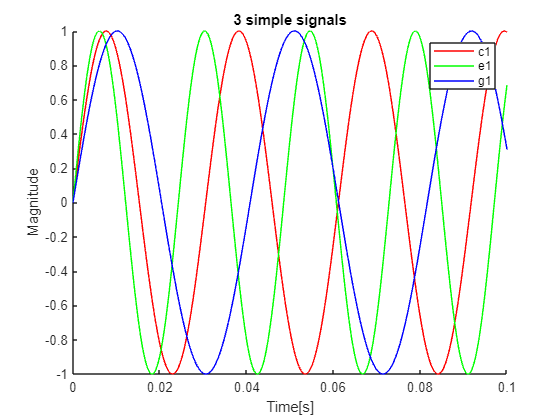

clear
frequency = 44100;
t = 3;
time_axis = 0:1/frequency:t;

c1 = 32.7;
e1 = 41.2;
g1 = 24.5;

frequency_1 = c1 * 2 * pi;
frequency_2 = e1 * 2 * pi;
frequency_3 = g1 * 2 * pi;
sig_1 = sin(time_axis * frequency_1); hold on
sig_2 = sin(time_axis * frequency_2); hold on
sig_3 = sin(time_axis * frequency_3); 
plot(time_axis, sig_1, "red");
plot(time_axis, sig_2, "green");
plot(time_axis, sig_3, "blue");
xlim([0,0.1])
xlabel("Time[s]");
ylabel("Magnitude");
title("3 simple signals");
legend("c1", "e1", "g1")
hold off

## **Composite signal**

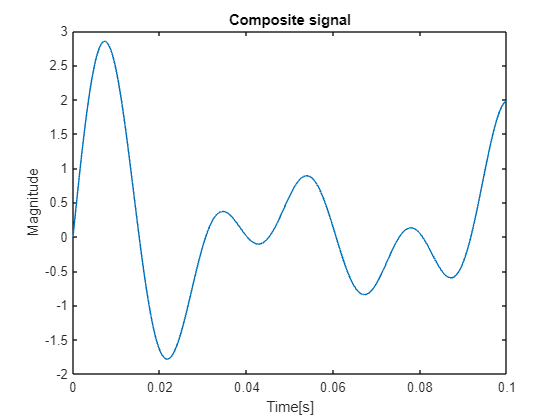

composite = sig_1 + sig_2 + sig_3;
plot(time_axis, composite);
title("Composite signal")
xlim([0, 0.1])
xlabel("Time[s]");
ylabel("Magnitude");

## **Broken nquist signal**

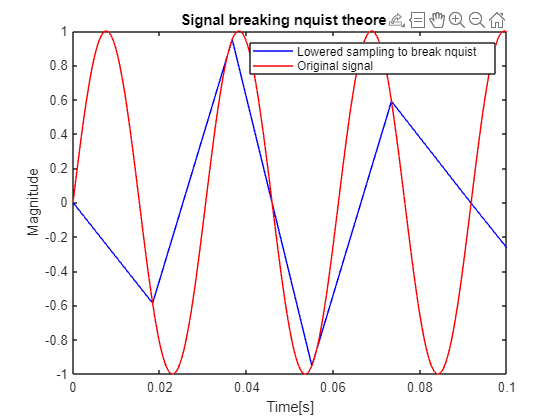

nquist_lim = round((frequency/ c1)/2);
sig_broken = downsample(sig_1, round(nquist_lim*1.2));
time_axis_broken = downsample(time_axis, round(nquist_lim*1.2));

plot(time_axis_broken, sig_broken, "blue"); hold on
plot(time_axis, sig_1, "red"); hold off
xlim([0,0.1])
title("Signal breaking nquist theorem");
xlabel("Time[s]");
ylabel("Magnitude");
legend("Lowered sampling to break nquist", "Original signal")

## **Úloha 2 **

Vygenerujte si jednoduchý signál. Pre okienko veľkosti 512 a okienko dĺžky, ktoré nezachytí ani celú základnú periódu (je príliš krátke) vypočítajte a vizualizujte DFT. Sú výstupné spektrá zhodné? Prečo je to tak?

## **Riešenie:**

## Priestor pre vaše funkcie:

## **DFT:**

function dft = calculate_dft(in)
    dft = zeros(0,512);
    for index = 1:1:512
        dft(index) = in(index) * exp(-index*2*pi);
    end
    1/512 .* dft;
end

Invalid expression. Check for missing or extra characters.